% Extreme daily max & minResult #2- Extreme daily max & min
% For the second result we look for the specific date during which the absolute maximum and minimum discharge happened in each year
% We provide the trend of the changes in the occurrence date 
% The results will be:
% The trend of the max & min discharge value over time
% The trend of the occurrence date over time

clc;
clear all;
clearvars;
close all;
filename = 'xlsx file location';

[NUM,TXT,RAW] = xlsread(filename,'sheetname');
tot_per= floor(size(NUM,1)/365);
k=1;
for jjj=1:tot_per
    clear A max_dis ind_max_dis date_max_dis min_dis ind_min_dis date_min_dis
    A(:,1) = NUM(k:jjj*365,1);
    A(:,2) = NUM(k:jjj*365,2);
%     max discharge value
    [max_dis ind_max_dis]=max(A(:,2));
    max_dis_v(jjj,1)=max_dis;
%     max discharge date
    date_max_dis=A(ind_max_dis,1);
    max_dis_d(jjj,1)=date_max_dis;
%     min discharge value
    [min_dis ind_min_dis]=min(A(:,2));
    min_dis_v(jjj,1)=min_dis;
%     min discharge date
    date_min_dis=A(ind_min_dis,1);
    min_dis_d(jjj,1)=date_min_dis;
    
    k=k+365;
end

% creating date dataset
n_day=[31 30 31 31 28 31 30 31 30 31 31 30];
mon=[10 11 12 1 2 3 4 5 6 7 8 9];
year_numbers=[1:tot_per]';

for i=1:tot_per
    corr_max_dis(i,1)=day(datestr(x2mdate(max_dis_d(i,1))));
    corr_max_dis(i,2)=month(datestr(x2mdate(max_dis_d(i,1))));
    corr_min_dis(i,1)=day(datestr(x2mdate(min_dis_d(i,1))));
    corr_min_dis(i,2)=month(datestr(x2mdate(min_dis_d(i,1))));
end

for i2=1:tot_per

[max_val_mon, max_ind_mon]=find(mon(1:12)==(corr_max_dis(i2,2)));
corr_max_dis(i2,3)=corr_max_dis(i2,1)+sum(n_day(1:max_ind_mon-1));

[min_val_mon, min_ind_mon]=find(mon(1:12)==(corr_min_dis(i2,2)));
corr_min_dis(i2,3)=corr_min_dis(i2,1)+sum(n_day(1:min_ind_mon-1));
end

bar(year_numbers(:,1),corr_max_dis(:,3),'EdgeColor','none','FaceColor',[0 0 0]);
hold 'on';
bar(85,238,'EdgeColor','none','FaceColor',[1 0.9 0.3]);
corr_max_dis2=corr_max_dis;
corr_max_dis2(85,3)=238;
P=polyfit(year_numbers(:,1),corr_max_dis2(:,3),1);
yfit = P(1)*year_numbers(:,1)+P(2);
hold on;
plot(year_numbers(:,1),yfit,'r-.','LineWidth',2);
xlabel('year')
ylabel('day')
% title('Tana, trend of the maximum discharge occurrence date')
set(gca,'FontSize',14,'FontWeight','Bold','FontName','Times New Roman','XTickLabel',...
    {'1911','1930','1950','1970','1990','2014'})
V_Pol=corr_max_dis(:,3);
alpha_Pol=0.05;
[H_Pol,p_value_Pol]=Mann_Kendall(V_Pol,alpha_Pol)

H_Pol = logical
   0


p_value_Pol = 0.0784

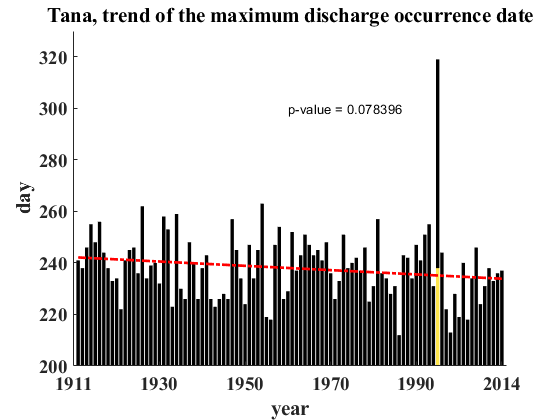

ylim([200 330]);
text1=['p-value = ' num2str(p_value_Pol)];
text(50,300,text1)
box('off')

close all;
bar(year_numbers(:,1),corr_min_dis(:,3),'EdgeColor','none','FaceColor',[0 0 0]);

P=polyfit(year_numbers(:,1),corr_min_dis(:,3),1);
yfit = P(1)*year_numbers(:,1)+P(2);
hold on;
plot(year_numbers(:,1),yfit,'r-.','LineWidth',2);
xlabel('year')
ylabel('day')
% title('Tana, trend of the minimum discharge occurrence date')

V_Pol=corr_min_dis(:,3);
alpha_Pol=0.05;
[H_Pol,p_value_Pol]=Mann_Kendall(V_Pol,alpha_Pol)

H_Pol = logical
   0


p_value_Pol = 0.2850

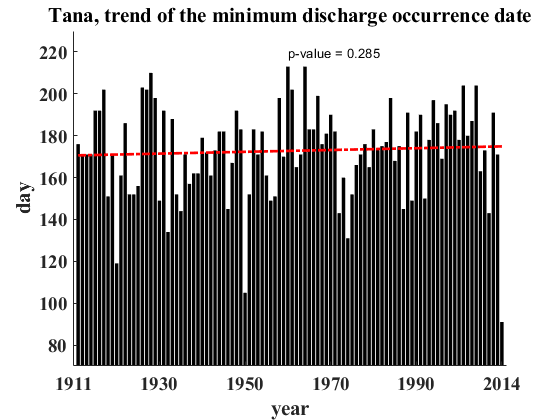

ylim([70 230]);
text1=['p-value = ' num2str(p_value_Pol)];
text(50,220,text1)
set(gca,'FontSize',14,'FontWeight','Bold','FontName','Times New Roman','XTickLabel',...
    {'1911','1930','1950','1970','1990','2014'})
box('off')

% Trend of discharge value

close all;
bar(year_numbers(:,1),max_dis_v(:,1),'EdgeColor','none','FaceColor',[0 0 0]);
P=polyfit(year_numbers(:,1),max_dis_v(:,1),1);
yfit = P(1)*year_numbers(:,1)+P(2);
hold on;
plot(year_numbers(:,1),yfit,'r-.','LineWidth',2);
xlabel('year')
ylabel('Discharge value (m^3/sec)')
% title('Tana, trend of the maximum discharge value')
set(gca,'FontSize',14,'FontWeight','Bold','FontName','Times New Roman','XTickLabel',...
    {'1911','1930','1950','1970','1990','2014'})
V_Pol=max_dis_v(:,1);
alpha_Pol=0.05;
[H_Pol,p_value_Pol]=Mann_Kendall(V_Pol,alpha_Pol)

H_Pol = logical
   0


p_value_Pol = 0.1303

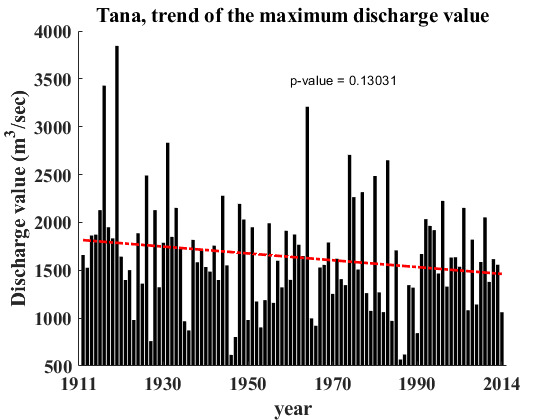

ylim([500 4000]);
text1=['p-value = ' num2str(p_value_Pol)];
text(50,3500,text1)
box('off')

close all;
bar(year_numbers(:,1),min_dis_v(:,1),'EdgeColor','none','FaceColor',[0 0 0]);
P=polyfit(year_numbers(:,1),min_dis_v(:,1),1);
yfit = P(1)*year_numbers(:,1)+P(2);
hold on;
plot(year_numbers(:,1),yfit,'r-.','LineWidth',2);

xlabel('year')
ylabel('Discharge value (m^3/sec)')
% title('Tana, trend of the minimum discharge value')
set(gca,'FontSize',14,'FontWeight','Bold','FontName','Times New Roman','XTickLabel',...
    {'1911','1930','1950','1970','1990','2014'})
V_Pol=min_dis_v(:,1);
alpha_Pol=0.05;
[H_Pol,p_value_Pol]=Mann_Kendall(V_Pol,alpha_Pol)

H_Pol = logical
   1


p_value_Pol = 1.5119e-06

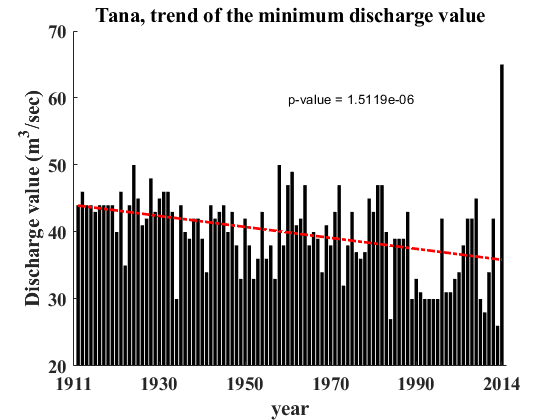

ylim([20 70]);
text1=['p-value = ' num2str(p_value_Pol)];
text(50,60,text1)
box('off')